# sub-06

This code begins by importing raw SEEG data and converting to Fieldtrip format. 

It then edit the SEEG channel labels, inspects the SEEG data, and remove any bad channels.

Following this, the code redefines resting, 0-back, 1-back and 2-back blocks using TRIG or Event channel signals.   

## Set working directory

clc;clear;close all;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\fieldtrip-20231220;
ft_defaults;
addpath Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\function\iEEGPrep
iEEGPrep_initial;
cd  Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS;
subID = 'sub-06';
cd(fullfile(subID, 'ieeg'));

## Import SEEG data and edit channel labels

% Import SEEG data into matlab using fieldtrip style
iEEGpath = [subID, '_task-resting_run-1_ieeg.edf'];
cfg = [];
cfg.dataset = iEEGpath;
Data = ft_preprocessing(cfg);

found matching BIDS sidecar 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-06\ieeg\sub-06_electrodes.tsv'
reading 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-06\ieeg\sub-06_electrodes.tsv'


 In ft_read_header at line 2937

processing channel { 'Event' 'TA1' 'TA2' 'TA3' 'TA4' 'TA5' 'TA6' 'TA7' 'TA8' 'TA9' 'TA10' 'TA11' 'TA12' 'TH1' 'TH2' 'TH3' 'TH4' 'TH5' 'TH6' 'TH7' 'TH8' 'TH9' 'TH10' 'TH11' 'TH12' 'PO1' 'PO2' 'PO3' 'PO4' 'PO5' 'PO6' 'PO7' 'PO8' 'PO9' 'PO10' 'PO11' 'PO12' 'TO1' 'TO2' 'TO3' 'TO4' 'TO5' 'TO6' 'TO7' 'TO8' 'TO9' 'TO10' 'P1' 'P2' 'P3' 'P4' 'P5' 'P6' 'P7' 'P8' 'P9' 'P10' 'T1' 'T2' 'T3' 'T4' 'T5' 'T6' 'C63' 'C64' 'C65' 'C66' 'C67' 'C68' 'C69' 'C70' 'C71' 'C72' 'C73' 'C74' 'C75' 'C76' 'C77' 'C78' 'C79' 'C80' 'C81' 'C82' 'C83' 'C84' 'C85' 'C86' 'C87' 'C88' 'C89' 'C90' 'C91' 'C92' 'C93' 'C94' 'C95' 'C96' 'C97' 'C98' 'C99' 'C100' 'C101' 'C102' 'C103' 'C104' 'C105' 'C106' 'C107' 'C108' 'C109' 'C110' 'C111' 'C112' 'C113' 'C114' 'C115' 'C116' 'C117' 'C118' 'C119' 'C120' 'C121' 'C122' 'C123' 'C124' 'C125' 'C126' 'C127' 'C128' 'DC1' 'DC2' 'DC3' 'DC4' 'DC5

Data.time{1} = Data.time{1}(1600000:3600000);
Data.trial{1} = Data.trial{1}(:, 1600000:3600000);
Data.sampleinfo = [1, length(Data.time{1})];
Event = abs(Data.trial{1}(146, :));
EventValue = unique(Event);
fsample = Data.fsample;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% rename channel labels
for i = 1:5;  Data.label{1+i} = ['TP', num2str(i)];end
for i = 1:12; Data.label{1+5+i} = ['TA''', num2str(i)];end
for i = 1:12; Data.label{1+5+12+i} = ['TB''', num2str(i)];end
for i = 1:5;  Data.label{1+5+12+12+i} = ['TO''', num2str(i)];end
for i = 1:10; Data.label{1+5+12+12+5+i} = ['F''', num2str(i)];end
for i = 1:8;  Data.label{1+5+12+12+5+10+i} = ['B''', num2str(i)];end
for i = 1:10; Data.label{1+5+12+12+5+10+8+i} = ['FU''', num2str(i)];end
for i = 1:12; Data.label{1+5+12+12+5+10+8+10+i} = ['S''', num2str(i)];end
for i = 1:12; Data.label{1+5+12+12+5+10+8+10+12+i} = ['MF''', num2str(i)];end

## Remove bad channels

% Remove non-iEEG channels
badChan = {};
for i = 87:128; badChan{i-86} = ['-C', num2str(i)]; end
for i = 1:16; badChan{128-87+1+i} = ['-DC', num2str(i)]; end
badChan = [badChan, {'-Event', '-TRIG', '-OSAT', '-PR', '-Pleth'}];
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove bad channels
badChan = {'-TA''7', '-TA''8', '-TB''1', '-TB''2'};
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


Data = rmfield(Data, 'elec');

## Inspects SEEG signals

BPfreq = [1, 120];
DataPrep = f_filter_bandpass(Data, BPfreq);

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 6 seconds


RSfreq = 250;
DataPrep = f_filter_resample(DataPrep, RSfreq);

the input is raw data with 82 channels and 1 trials
the call to "ft_selectdata" took 0 seconds
resampling data
resampling data in trial 1 from 1

original sampling rate = 2.047999e+03 Hz
new sampling rate = 2.499998e+02 Hz
the call to "ft_resampledata" took 2 seconds


chanGroups = f_chanGroup(DataPrep.label);
refMethod = 'CommonAverage';
DataPrep = f_reref_SEEG(DataPrep, refMethod, chanGroups);

 In fixsampleinfo at line 100
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279



 In fixsampleinfo at line 105
 In ft_datatype_raw at line 148
 In ft_checkdata at line 279

the call to "ft_selectdata" took 0 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 0 seconds


the input is raw data with 82 channels and 1 trials


detected   0 visual artifacts
the different artifact types correspond to the following colors:
  visual = pink
the different event types correspond to the following colors:


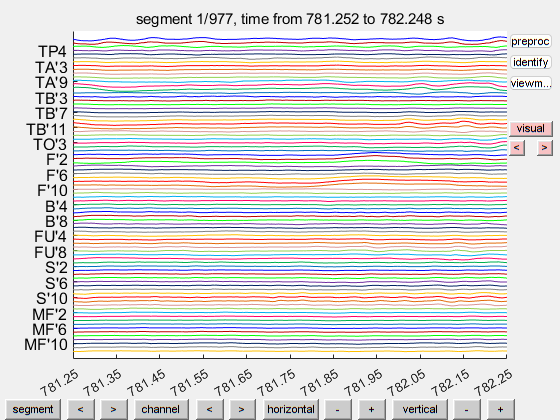

------------------------------------------------------------------------------------
You can use the following keyboard buttons in the databrowser
1-9                : select artifact type 1-9
shift 1-9          : select previous artifact of type 1-9 (does not work with numpad)
alt 1-9            : select next artifact of type 1-9
arrow-left         : previous trial
arrow-right        : next trial
shift arrow-up     : increase vertical scaling
shift arrow-down   : decrease vertical scaling
shift arrow-left   : increase horizontal scaling
shift arrow-down   : decrease horizontal scaling
t                  : open trial or segment selection dialog
c                  : open channel selection dialog
h                  : open horizontal scaling dialog
v                  : open vertical scaling dialog
p                  : open preproc editor
i                  : identify a specific channel
m                  : toggles between cfg.viewmode options
s                  : toggles between cfg.selec

cfg = [];
cfg.viewmode = 'vertical';
ft_databrowser(cfg, DataPrep);

## Redefine the resting block

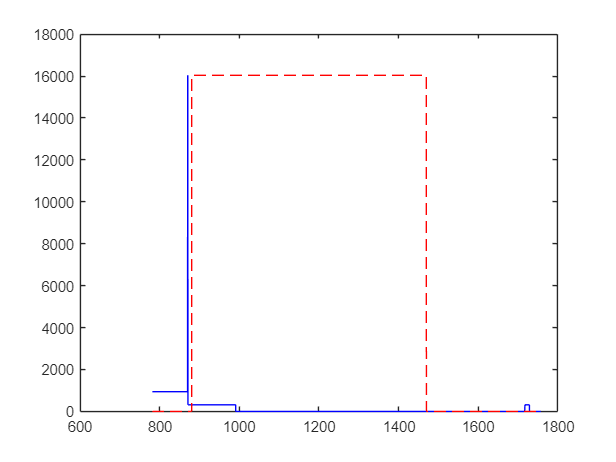

rsValue = EventValue(4);
rsPointer = Event == rsValue;
rsStart = find(diff(rsPointer)==1);
rsStart = rsStart + ceil(10*fsample);
rsEnd = rsStart + ceil(10*60*fsample-10*fsample);
rsPointer = zeros(size(Event));
rsPointer(rsStart:rsEnd) = rsValue;
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, rsPointer, '--r');
hold off;

% Construct data
rsSignals = Data.trial{1}(:, rsStart:rsEnd);
sampleinfo = [1, size(rsSignals, 2)];
rsTime = Data.time{1}(rsStart:rsEnd);
rsData.cfg = Data.cfg;
rsData.fsample = fsample;
rsData.label = Data.label;
rsData.hdr = Data.hdr;
rsData.trial{1} = rsSignals;
rsData.time{1} = rsTime;
rsData.sampleinfo = sampleinfo;
save([subID, '_task-resting_run-1_ieeg.mat'], 'rsData');
disp('**************************************************');

**************************************************


## Redefione 0-back blocks

clc;clear;close all;
subID = 'sub-06';
iEEGpath = [subID, '_task-resting_run-1_ieeg.edf'];
cfg = [];
cfg.dataset = iEEGpath;
Data1 = ft_preprocessing(cfg);

found matching BIDS sidecar 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-06\ieeg\sub-06_electrodes.tsv'
reading 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-06\ieeg\sub-06_electrodes.tsv'


 In ft_read_header at line 2937

processing channel { 'Event' 'TA1' 'TA2' 'TA3' 'TA4' 'TA5' 'TA6' 'TA7' 'TA8' 'TA9' 'TA10' 'TA11' 'TA12' 'TH1' 'TH2' 'TH3' 'TH4' 'TH5' 'TH6' 'TH7' 'TH8' 'TH9' 'TH10' 'TH11' 'TH12' 'PO1' 'PO2' 'PO3' 'PO4' 'PO5' 'PO6' 'PO7' 'PO8' 'PO9' 'PO10' 'PO11' 'PO12' 'TO1' 'TO2' 'TO3' 'TO4' 'TO5' 'TO6' 'TO7' 'TO8' 'TO9' 'TO10' 'P1' 'P2' 'P3' 'P4' 'P5' 'P6' 'P7' 'P8' 'P9' 'P10' 'T1' 'T2' 'T3' 'T4' 'T5' 'T6' 'C63' 'C64' 'C65' 'C66' 'C67' 'C68' 'C69' 'C70' 'C71' 'C72' 'C73' 'C74' 'C75' 'C76' 'C77' 'C78' 'C79' 'C80' 'C81' 'C82' 'C83' 'C84' 'C85' 'C86' 'C87' 'C88' 'C89' 'C90' 'C91' 'C92' 'C93' 'C94' 'C95' 'C96' 'C97' 'C98' 'C99' 'C100' 'C101' 'C102' 'C103' 'C104' 'C105' 'C106' 'C107' 'C108' 'C109' 'C110' 'C111' 'C112' 'C113' 'C114' 'C115' 'C116' 'C117' 'C118' 'C119' 'C120' 'C121' 'C122' 'C123' 'C124' 'C125' 'C126' 'C127' 'C128' 'DC1' 'DC2' 'DC3' 'DC4' 'DC5

iEEGpath =  [subID, '_task-nback_run-1_ieeg.edf'];
cfg = [];
cfg.dataset = iEEGpath;
Data2 = ft_preprocessing(cfg);

found matching BIDS sidecar 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-06\ieeg\sub-06_electrodes.tsv'
reading 'Z:\xwiEEG_WorkingMemory_zhangshen\github_replication\data_prep\BIDS\sub-06\ieeg\sub-06_electrodes.tsv'


 In ft_read_header at line 2937

processing channel { 'Event' 'TA1' 'TA2' 'TA3' 'TA4' 'TA5' 'TA6' 'TA7' 'TA8' 'TA9' 'TA10' 'TA11' 'TA12' 'TH1' 'TH2' 'TH3' 'TH4' 'TH5' 'TH6' 'TH7' 'TH8' 'TH9' 'TH10' 'TH11' 'TH12' 'PO1' 'PO2' 'PO3' 'PO4' 'PO5' 'PO6' 'PO7' 'PO8' 'PO9' 'PO10' 'PO11' 'PO12' 'TO1' 'TO2' 'TO3' 'TO4' 'TO5' 'TO6' 'TO7' 'TO8' 'TO9' 'TO10' 'P1' 'P2' 'P3' 'P4' 'P5' 'P6' 'P7' 'P8' 'P9' 'P10' 'T1' 'T2' 'T3' 'T4' 'T5' 'T6' 'C63' 'C64' 'C65' 'C66' 'C67' 'C68' 'C69' 'C70' 'C71' 'C72' 'C73' 'C74' 'C75' 'C76' 'C77' 'C78' 'C79' 'C80' 'C81' 'C82' 'C83' 'C84' 'C85' 'C86' 'C87' 'C88' 'C89' 'C90' 'C91' 'C92' 'C93' 'C94' 'C95' 'C96' 'C97' 'C98' 'C99' 'C100' 'C101' 'C102' 'C103' 'C104' 'C105' 'C106' 'C107' 'C108' 'C109' 'C110' 'C111' 'C112' 'C113' 'C114' 'C115' 'C116' 'C117' 'C118' 'C119' 'C120' 'C121' 'C122' 'C123' 'C124' 'C125' 'C126' 'C127' 'C128' 'DC1' 'DC2' 'DC3' 'DC4' 'DC5

Data = Data2;
Data.time{1} = [Data1.time{1}, Data1.time{1}(end)+Data2.time{1}];
Data.trial{1} = [Data1.trial{1}, Data2.trial{1}];
Data.time{1} = Data.time{1}(4100000:7300000);
Data.trial{1} = Data.trial{1}(:, 4100000:7300000);
Data.sampleinfo = [1, length(Data.time{1})];
Event = abs(Data.trial{1}(146, :));
EventValue = unique(Event);
fsample = Data.fsample;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Rename channels
for i = 1:5;  Data.label{1+i} = ['TP', num2str(i)];end
for i = 1:12; Data.label{1+5+i} = ['TA''', num2str(i)];end
for i = 1:12; Data.label{1+5+12+i} = ['TB''', num2str(i)];end
for i = 1:5;  Data.label{1+5+12+12+i} = ['TO''', num2str(i)];end
for i = 1:10; Data.label{1+5+12+12+5+i} = ['F''', num2str(i)];end
for i = 1:8;  Data.label{1+5+12+12+5+10+i} = ['B''', num2str(i)];end
for i = 1:10; Data.label{1+5+12+12+5+10+8+i} = ['FU''', num2str(i)];end
for i = 1:12; Data.label{1+5+12+12+5+10+8+10+i} = ['S''', num2str(i)];end
for i = 1:12; Data.label{1+5+12+12+5+10+8+10+12+i} = ['MF''', num2str(i)];end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove non-ieeg channels
badChan = {};
for i = 87:128; badChan{i-86} = ['-C', num2str(i)]; end
for i = 1:16; badChan{128-87+1+i} = ['-DC', num2str(i)]; end
badChan = [badChan, {'-Event', '-TRIG', '-OSAT', '-PR', '-Pleth'}];
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Remove bad channels
badChan = {'-TA''7', '-TA''8', '-TB''1', '-TB''2'};
cfg = [];
cfg.channel = [{'all'}, badChan];
Data = ft_preprocessing(cfg, Data);

the call to "ft_selectdata" took 1 seconds
preprocessing
preprocessing trial 1 from 1

the call to "ft_preprocessing" took 1 seconds


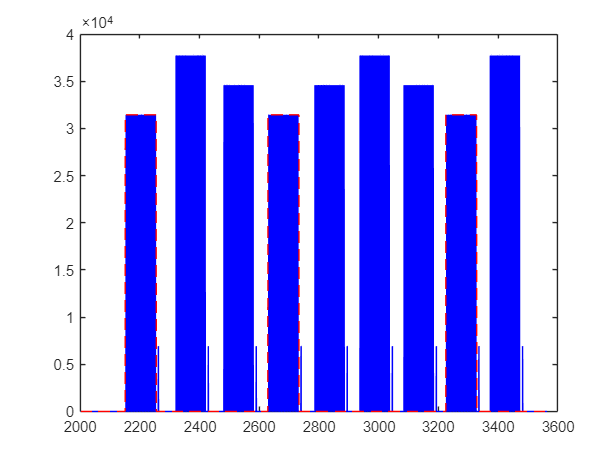

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 0-back event
nb0Value = EventValue(3);
nb0Pointer = Event == nb0Value;
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Pointer = zeros(size(Event));
for nn = 1:length(nb0Start)
    nb0Pointer(nb0Start(nn)-ceil(3*fsample):nb0End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb0Value*nb0Pointer, '--r');
hold off;

% Construct data
nb0Start = find(diff(nb0Pointer)==1);
nb0End = find(diff(nb0Pointer)==-1);
nb0Data.cfg = Data.cfg;
nb0Data.fsample = fsample;
nb0Data.label = Data.label;
nb0Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb0Start(nRun), nb0End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb0Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb0Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb0Data.sampleinfo(nRun, :) = sampleinfo;
    nb0Data.time{nRun} = nb0Time;
    nb0Data.trial{nRun} = nb0Signal;
end
save([subID, '_task-0back_run-1_ieeg.mat'], 'nb0Data', 'TRIG');
disp('**************************************************');

**************************************************


## Redefine 1-back blocks

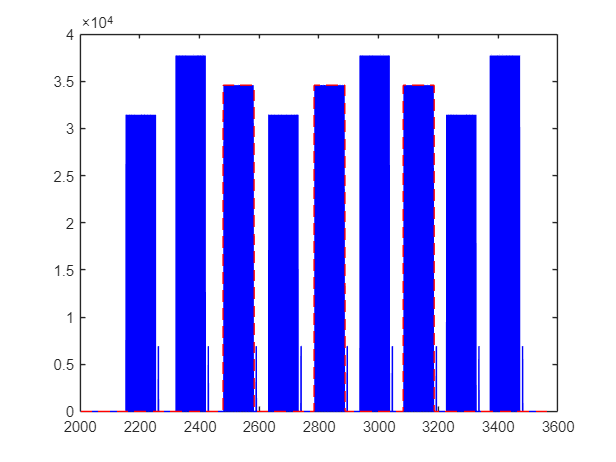

nb1Value = EventValue(4);
nb1Pointer = Event == nb1Value;
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Pointer = zeros(size(Event));
for nn = 1:length(nb1Start)
    nb1Pointer(nb1Start(nn)-ceil(3*fsample):nb1End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb1Value*nb1Pointer, '--r');
hold off;

% Construct data
nb1Start = find(diff(nb1Pointer)==1);
nb1End = find(diff(nb1Pointer)==-1);
nb1Data.cfg = Data.cfg;
nb1Data.fsample = fsample;
nb1Data.label = Data.label;
nb1Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb1Start(nRun), nb1End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb1Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb1Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb1Data.sampleinfo(nRun, :) = sampleinfo;
    nb1Data.time{nRun} = nb1Time;
    nb1Data.trial{nRun} = nb1Signal;
end
save([subID, '_task-1back_run-1_ieeg.mat'], 'nb1Data', 'TRIG');
disp('******************************');

******************************


## Redefine 2-back blocks

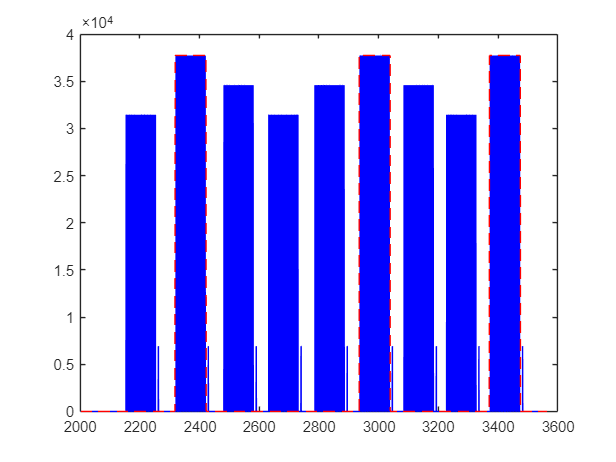

nb2Value = EventValue(5);
nb2Pointer = Event == nb2Value;
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Pointer = zeros(size(Event));
for nn = 1:length(nb2Start)
    nb2Pointer(nb2Start(nn)-ceil(3*fsample):nb2End(nn)+ceil(3*fsample))=1;
end
figure;
plot(Data.time{1}, Event, '-b');
hold on;
plot(Data.time{1}, nb2Value*nb2Pointer, '--r');
hold off;

% Construct data
nb2Start = find(diff(nb2Pointer)==1);
nb2End = find(diff(nb2Pointer)==-1);
nb2Data.cfg = Data.cfg;
nb2Data.fsample = fsample;
nb2Data.label = Data.label;
nb2Data.hdr = Data.hdr;
for nRun = 1:3
    sampleinfo = [nb2Start(nRun), nb2End(nRun)];
    TRIG{nRun} = Event(sampleinfo(1):sampleinfo(2));
    nb2Signal = Data.trial{1}(:, sampleinfo(1):sampleinfo(2));
    nb2Time = Data.time{1}(sampleinfo(1):sampleinfo(2));
    nb2Data.sampleinfo(nRun, :) = sampleinfo;
    nb2Data.time{nRun} = nb2Time;
    nb2Data.trial{nRun} = nb2Signal;
end
save([subID, '_task-2back_run-1_ieeg.mat'], 'nb2Data', 'TRIG');